any periodic function can be expressed in the form


$$x(t) = \frac{a_0}{2} 
+ \sum_{n=1}^{\infty}
(a_n \cos n \omega t + b_n \sin n \omega t)
\quad
\omega = 2\pi/\tau$$


where all the coefficients are constant. 

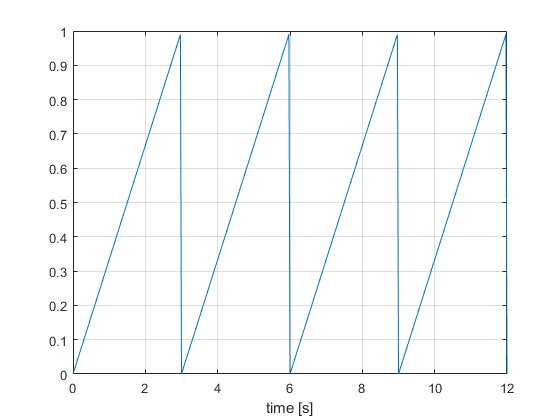

clear
tau=3; %period
npt=100;
t=0:tau/npt:4*tau;
A=1;
pf=TriangularWave(t,A,tau);
figure
plot(t,pf); xlabel('time [s]'); grid on;

fprintf(1,'period %f [s] \n',tau);

period 3.000000 [s] 


harmonic analisys using numerical integration


$$a_0 = {2 \over \tau} \int_0^\tau x(t) dt$$
  


$$a_n = {2 \over \tau} \int_0^\tau x(t) \cos( n \omega t) dt$$
   
$$b_n = {2 \over \tau} \int_0^\tau x(t) \sin( n \omega t) dt$$



nArm=40; % number of approximating harmonic functions (it means 10 natural frequency)
N=npt;
tp=0:tau/N:tau;
Dt = tp(2)-tp(1);
a0=0; %numerical integration over the period
for k=1:N
    a0 = a0+TriangularWave(tp(k),A,tau)*Dt;
end
a0 = a0*2/tau;
an=zeros(nArm,1);
bn=zeros(nArm,1);

wn=2*pi/tau;
for a=1:nArm
    for k=1:N
        an(a) = an(a) + TriangularWave(tp(k),A,tau)*cos(a*wn*tp(k))*Dt;  
        bn(a) = bn(a) + TriangularWave(tp(k),A,tau)*sin(a*wn*tp(k))*Dt;  
    end
    an(a) = an(a)*2/tau;
    bn(a) = bn(a)*2/tau;
end


components of the series

fprintf(1,'components of the series (%d harmonics)', nArm)

components of the series (40 harmonics)

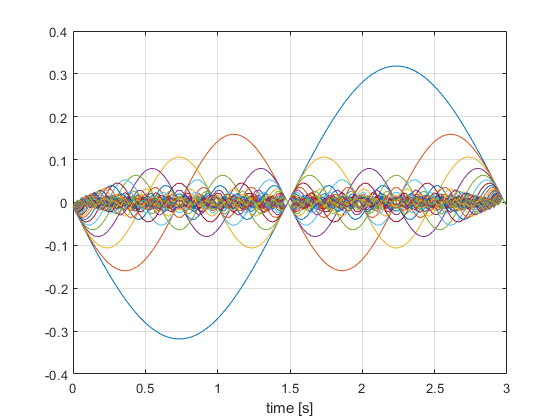

figure
for k=1:nArm
    y = an(k)*cos(k*wn*tp) + bn(k)*sin(k*wn*tp);
    plot(tp,y); hold on
    % omega is constant end k is the number of armonic function
    % the second period is the double of the first one
    
end
grid on;
xlabel('time [s]')

% the approssimation is not so good in the case



$$x(t) = \frac{a_0}{2} 
+ \sum_{n=1}^{\infty}
(a_n \cos n \omega t + b_n \sin n \omega t)
\quad
\omega = 2\pi/\tau$$


disp('signal approximation (frequency spectrum)')

signal approximation (frequency spectrum)


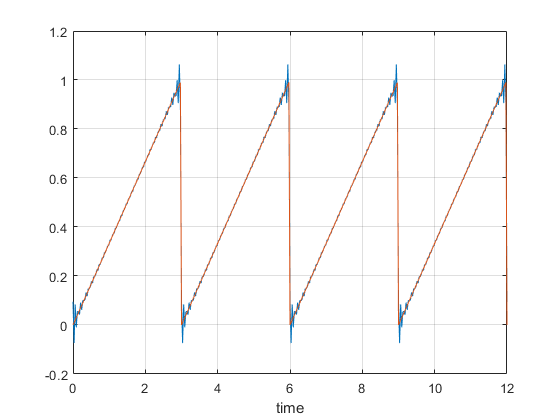

hf = harmonicFun(a0,an,bn,tau,nArm,t);
figure
plot(t,hf,t,pf);grid on;
xlabel('time');


w=2*pi/tau;
vf=(1:nArm)/tau;

disp('frequency components')

frequency components


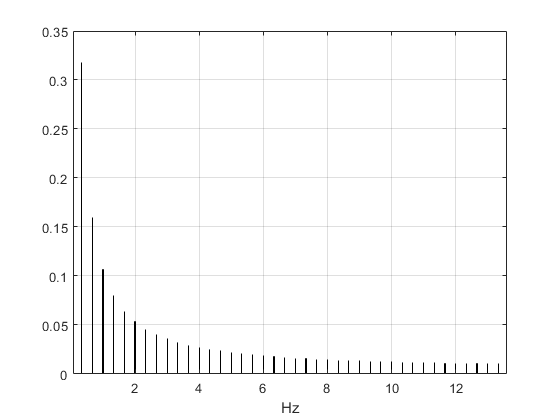

figure
bar(vf,sqrt(an.^2+bn.^2),0.01);grid on;
xlabel('Hz')